# Taller 14

### 11/21/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 12 y 13*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

- **Otros recursos sobre manejo de MATLAB practicas básicas: **[*https://matlabacademy.mathworks.com/es/*](https://matlabacademy.mathworks.com/es/)

*Notas sobre la teoria:*

`Algunas ecuaciones de avance para los métodos númericos son:`

- `Euler`

  

- `Taylor orden M`

- `Euler Modificado`

- `Heun`

        

- `Runge-Kutta orden 4`

        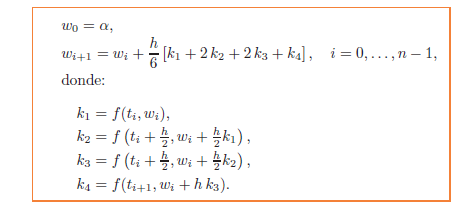

- `Diferencias finitas centradas`

     

- `Diferencias finitas en ecuaciones diferenciales parciales`

   

`El método de disparo lineal, recordar que se realiza la transformación de EDO con condiciones Dirichlet a un sistema Cauchy`

`Con solución:`

*Notas sobre los métodos:*

**    Solución Númerica de ecuaciones diferenciales:**

`R = rk4 (f, a, b, ya, M)`` : La versión multivariada es` `rks4`

`        - f funcion creada con @`

`        - a y b son los extremos izquierdo y derecho`

`        - ya es la condicion inicial  y(a)`

`        - M es el numero de pasos`

`        - R = [T', Y'] donde  T  es el vector de abscisas`

`            y  Y  es el vector de ordenadas`

`L = linsht (F1, F2, a, b, alpha, beta, M)`

                `- F1 y F2 son los sistemas de ecuaciones de primer orden`

                `    representando los Problemas de Valor Inicial (P.V.I.'s)`

                `    (9) and (10), respectivamente; funciones creadas con @`

                `- a y b son los extremos del intervalo`

                `- alpha = x(a)  y  beta = x(b); las condiciones frontera`

                `- M es el numero de pasos`

                `- L = [T', X]; donde  T' es el vector de abscisas (M+1) x 1`

                `    y  X  es el vector de ordenadas  (M+1) x 1`

`F = findiff (p, q, r, a, b, alpha, beta, N)`

                `- p, q, r  son las funciones coeficientes de`

                `    f(t,x,x')=p(t)x'+q(t)x+r(t) introducidas con @`

                `- a y b son los extremos izquierdo y derecho`

                `- alpha = x(a)  y  beta = x(b)`

                `- N es el numero de pasos`

                `- F = [T', X']: donde T' es el vector de abscisas  1 x N  y`

                `    X' es el vector de ordenadas  1 x N.`

`U = poisson(g,f1,f2,f3,f4,a,b,c,d,m,n)`

`poisson.m  -- Resuelve el problema de Poisson u_{xx} + u_{yy} = g(x,y)`

`en [a,b] x [c,d], usando el metodo de diferencias finitas de cinco puntos`

`        - g funcion creada con @`

                `- f1 es la condicion de frontera abajo (en y=c) funcion creada con @`

                `- f2 es la condicion de frontera derecha (en x=b) funcion creada con @`

                `- f3 es la condicion de frontera arriba (en y=d) funcion creada con @`

                `- f4 es la condicion de frontera izquierda (en x=a) funcion creada con @`

                `    Las funciones f1, f2, f3 y f4 se ingresan como cadenas de carateres`

                `- m es el numero de puntos sobre el eje x`

                `- n es el numero de puntos sobre el eje y`

*Recordar documentarse en cada una de las rutinas disponibles del curso y de MATLAB para afrontar distintas situaciones, MATLAB es su aliado.*

`Punto 1. ``Diferencias finitas vs Disparo Lineal`

clear

F = @(x, U) [U(2), 1./x.^2 .* (2 * log(x) - 4*x .* U(2) - 2*U(1))];

D1 = @(x, U) F(x, U);
D2 = @(x, U) [U(2), 1./x.^2 .* (-4*x .* U(2) - 2*U(1))];

a = 1; b = 2; h = .1; M = round((b - a)/h);

[X, U] = puntomedios(D1, a, b, [.5 0], M);
[~, V] = puntomedios(D2, a, b, [0 1], M);

Y = U(:, 1) + (log(2) - U(end, 1)) / V(end, 1) * V(:, 1);

p = @(x) - 4 * x ./ x.^2;
q = @(x) -2 ./ x.^2;
r = @(x) 2 * log(x) ./x.^2;

DF = findiff(p, q, r, 1, 2, .5, log(2), M);

clf('reset')
hold on
plot(X, DF(:, 2), 'DisplayName', 'Diferencias finitas')
plot(X, Y, 'DisplayName', 'Disparo Lineal')
legend('Location', 'best')
grid on
hold off

`Punto 2. ``Diferencias finitas & Orden de convergencia`

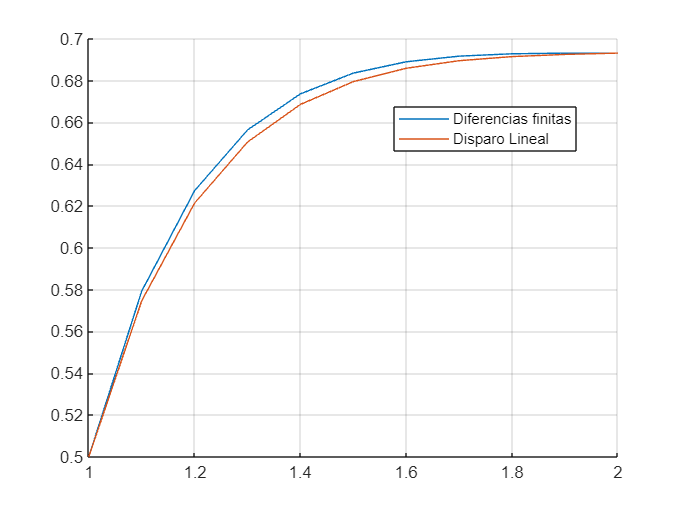

clear

F = @(x, U) [U(2), 1./(1 + x.^2).^2 .* (2 + x.^2 .* cos(x) / (1 + x.^2) ...

                                      - x.*cos(x) .* U(2) + cos(x) *U(1))];

p = @(x) - x.*cos(x) ./(1 + x.^2).^2;
q = @(x) cos(x)./(1 + x.^2).^2;
r = @(x) (2 + x.^2 .* cos(x) / (1 + x.^2)) .* 1./(1 + x.^2).^2;

D1 = @(x, U) F(x, U);
D2 = @(x, U) [U(2), 1./(1 + x.^2).^2 .* (- x.*cos(x) .* U(2) + ...
                                                    cos(x) *U(1))];
N = 2 / .25;
DF = findiff(p, q, r, 5, 7, 6.868, 10, N);
LS = linsht(D1, D2, 5, 7, 6.868, 10, N);

y = @(x) x .* atan(x);

clf('reset')
hold on
fplot(y, [5, 7],'k', 'DisplayName', 'Función Original')
plot(DF(:, 1), DF(:, 2), '.-', 'DisplayName', 'Diferencias finitas')
plot(LS(:, 1), LS(:, 2), '.-', 'DisplayName', 'Disparo Lineal')
legend('Location', 'best')
grid on
hold off
X = LS(:, 1);
ELS = abs(y(X) - LS(:, 2))'
EDF = abs(y(X) - DF(:, 2))'
EDF = EDF ./ y(X)', ELS = ELS ./ y(X)'

`Punto 4. Generación de mallas`

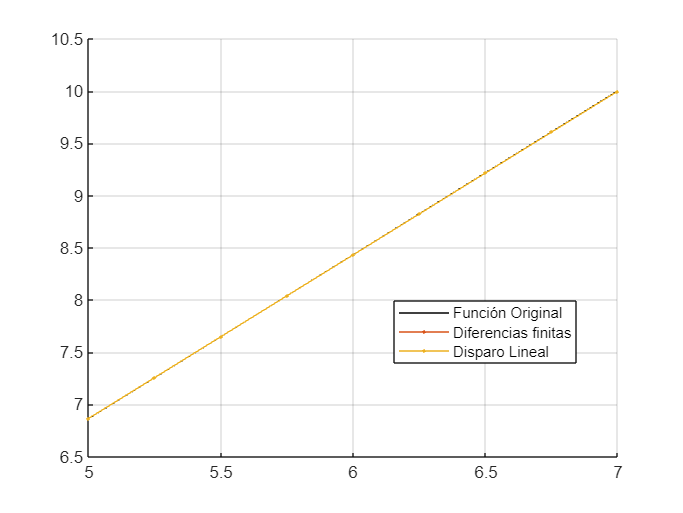

clear

syms A B C D E x y h k W real
syms w [1 5]

ELS =     0.0010    0.0006    0.0002    0.0002    0.0007    0.0011    0.0015    0.0019    0.0023


EDF =     0.0010    0.0006    0.0001    0.0003    0.0007    0.0011    0.0015    0.0019    0.0023


w = [.75 A .75 .6667 .6667;

EDF = 1.0e-03 *

    0.1451    0.0765    0.0186    0.0323    0.0783    0.1206    0.1597    0.1960    0.2294


ELS = 1.0e-03 *

    0.1451    0.0804    0.0224    0.0299    0.0773    0.1205    0.1599    0.1961    0.2294


     1.0714 .9813 B .8891 .9091;
     1.3125 E 1.0535 1.0264 D;
     1.5 1.0909 1 C 1.2];

disp(vpa(w))
X = 1:1/4:2; Y = 1:2/3:3; h = 1/4; k = 2/3;

Utilizando las relaciones de diferencias finitas, tenemos que:


$$\frac{\partial^2 U}{\partial x^2 }=\frac{w_{i+1j} -{2w}_{\mathrm{ij}} +w_{i-1j} }{h^2 }$$


 
$$\frac{w_{i+1j} -{2w}_{\mathrm{ij}} +w_{i-1j} }{h^2 }+\frac{w_{\mathrm{ij}+1} -{2w}_{\mathrm{ij}} +w_{\mathrm{ij}-1} }{k^2 }=\frac{x_i \;y_j }{2x_i +y_j }$$


LHS(W, w1, w2, w3, w4) = 1/h^2 * (w1 - 2*W + w2) + 1/k^2 * (w3 - 2*W + w4);
RHS(x, y) = x*y / (2*x + y);

Eq(W, w1, w2, w3, w4, x, y) = LHS(W, w1, w2, w3, w4) == RHS(x, y)
EqB = Eq(w(2, 3), w(2, 4), w(2, 2), w(3, 3), w(1, 3), X(3), Y(2))
b = vpa(vpasolve(EqB), 6)

$$\left(\begin{array}{ccccc} 0.75 & A & 0.75 & 0.6667 & 0.6667\\ 1.0714 & 0.9813 & B & 0.8891 & 0.9091\\ 1.3125 & \text{E} & 1.0535 & 1.0264 & \text{D}\\ 1.5 & 1.0909 & 1.0 & C & 1.2 \end{array}\right)$$

EqE = Eq(w(3, 2), w(3, 3), w(3, 1), w(2, 2), w(4, 2), X(2), Y(3))
e = vpa(vpasolve(EqE), 6)
w = subs(w, [B E], [b e]);
EqA = Eq(w(2, 2), b, w(2, 1), e, w(1, 2), X(2), Y(2))
a = vpa(solve(EqA), 6)
u(x) = 6 / (2*x + 3);
c = vpa(u(X(4)), 6)
u(y) = 2*y / (2 + y);

$$Eq(W, w1, w2, w3, w4, x, y) = 16\,w_{1}-\frac{73\,W}{2}+16\,w_{2}+\frac{9\,w_{3}}{4}+\frac{9\,w_{4}}{4}=\frac{x\,y}{2\,x+y}$$

d = vpa(u(Y(3)), 6)

$$EqB = \frac{1359371}{40000}-\frac{73\,B}{2}=\frac{15}{28}$$

U = vpa(subs(w, [A B C D E], [a b c d e]), 6)

$$b = 0.916399$$

X = repmat(X, [4, 1]); Y = repmat(Y, [5, 1])';

$$EqE = \frac{850369}{20000}-\frac{73\,\text{E}}{2}=\frac{35}{58}$$

$$e = 1.14836$$

clf('reset')
hold on

$$EqA = \frac{9\,A}{4}-1.4288657449895404548215129225994=\frac{1}{2}$$

mesh(X, Y, U)

$$a = 0.857274$$

plot3(X, Y, U, '.', 'MarkerSize', 12)
grid on

$$c = 0.923077$$

hold off

`Punto 5. Problema Eliptico Modificiado`

Utilizando las relaciones de diferencias finitas, tenemos que:

$\frac{\partial^2 U}{\partial x^2 }=\frac{w_{i+1j} -{2w}_{\mathrm{ij}} +w_{i-1j} }{h^2 }$, $\frac{\;\partial \;U}{\partial x}=\frac{w_{ij} -w_{i-1j} }{h}$

 
$$\frac{w_{\mathrm{ij}+1} -{2w}_{\mathrm{ij}} +w_{\mathrm{ij}-1} }{k^2 }\;+\;\frac{1}{16}\;\frac{w_{i+1j} -{2w}_{\mathrm{ij}} +w_{i-1j} }{h^2 }+\frac{1}{4}\;\frac{w_{\mathrm{ij}} -w_{i-1j} }{h}=x_i +\exp \left(y_j -2\right)$$


clear

$$d = 1.07692$$

syms A B C D x y W real

$$U = \left(\begin{array}{ccccc} 0.75 & 0.857274 & 0.75 & 0.6667 & 0.6667\\ 1.0714 & 0.9813 & 0.916399 & 0.8891 & 0.9091\\ 1.3125 & 1.14836 & 1.0535 & 1.0264 & 1.07692\\ 1.5 & 1.0909 & 1.0 & 0.923077 & 1.2 \end{array}\right)$$

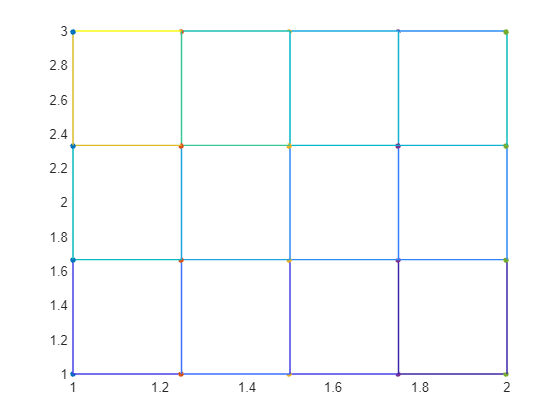

syms w [1 5]

X = 1:1/4:1.5; Y = 2:1/3:3; h = 1/4; k = 1/3;
Ix(y) = 1 + exp(y - 2); Sx(y) = 1.5 + exp(y-2);
Iy(x) = x + 1; Sy(x) = x + 2.72;

u = [Iy(X); Ix(Y(2)) A Sx(Y(2)); Ix(Y(3)) B Sx(Y(3)); Sy(X)]
LHS(W, w1, w2, w3, w4) = 1/k^2 * (w3 - 2*W + w4) + ...

           1/16 * 1/h^2 * (w1 - 2*W + w2) + 1/4 * 1 / h * (W - w2);
RHS(x, y) = x + exp(y - 2);

Eq(W, w1, w3, w4, x, y) = LHS(W, w1, w2, w3, w4) == RHS(x, y)
EqA = Eq(u(2, 2), u(2, 3), u(3, 2), u(1, 2), X(2), Y(2));
EqB = Eq(u(3, 2), u(3, 3), u(4, 3), u(2, 3), X(2), Y(3));
S = solve(EqA, EqB);
a = vpa(S.A, 6), b = vpa(S.B, 6);
U = vpa(subs(u, [A B], [a b]), 6)
X = repmat(X, [4, 1]), Y = repmat(Y, [3, 1])'
clf('reset')
hold on
mesh(X, Y, U)
plot3(X, Y, U, '.', 'MarkerSize', 12)

$$u = \left(\begin{array}{ccc} 2 & \frac{9}{4} & \frac{5}{2}\\ {\mathrm{e}}^{1/3}+1 & A & {\mathrm{e}}^{1/3}+\frac{3}{2}\\ {\mathrm{e}}^{2/3}+1 & B & {\mathrm{e}}^{2/3}+\frac{3}{2}\\ \frac{93}{25} & \frac{397}{100} & \frac{211}{50} \end{array}\right)$$

$$Eq(W, w1, w3, w4, x, y) = w_{1}-19\,W+9\,w_{3}+9\,w_{4}=x+{\mathrm{e}}^{y-2}$$

$$a = 2.68176$$

$$U = \left(\begin{array}{ccc} 2.0 & 2.25 & 2.5\\ 2.39561 & 2.68176 & 2.89561\\ 2.94773 & 3.38371 & 3.44773\\ 3.72 & 3.97 & 4.22 \end{array}\right)$$

X =     1.0000    1.2500    1.5000
    1.0000    1.2500    1.5000
    1.0000    1.2500    1.5000
    1.0000    1.2500    1.5000


Y =     2.0000    2.0000    2.0000
    2.3333    2.3333    2.3333
    2.6667    2.6667    2.6667
    3.0000    3.0000    3.0000


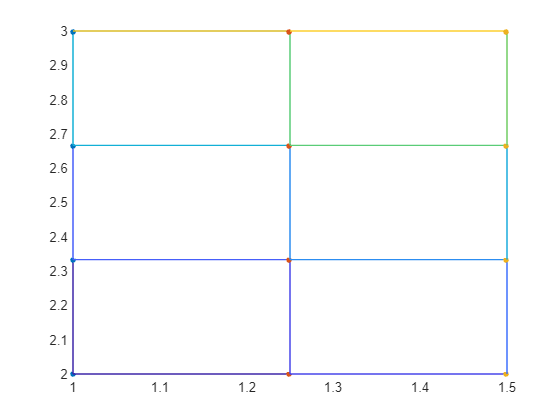

grid on
hold off